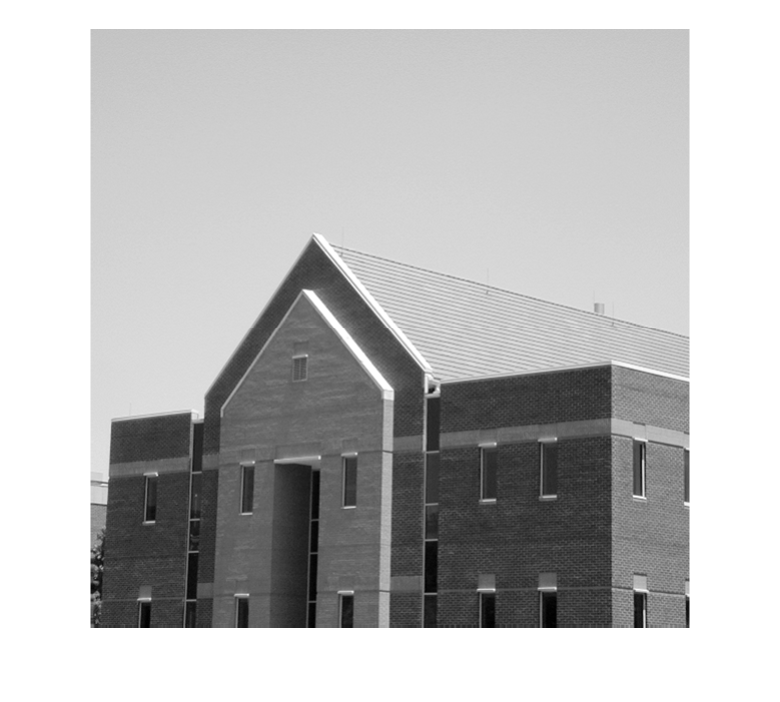

I = im2gray(imread("Fig0438(a)(bld_600by600).tif"));
imshow(I)

theta = pi/4;
T_matrix = [cos(theta) sin(theta) 0;
      -sin(theta) cos(theta) 0;
      0           0           1];
% tform = affinetform2d(T_matrix);
% I_trasformed = imwarp(I, tform);
T_matrix = inv(T_matrix);

I_trasformed = zeros(size(I));
Rows = size(I,1);
Cols = size(I,2);
for i = 1:1:Rows+400
    for j = 1:1:Cols+400
        T_cords = [i j 1] * T_matrix;
        T_x = T_cords(1);
        T_y = T_cords(2);
         if T_x <= 0 || T_x > Rows || T_y <= 0 || T_y > Cols
            continue
         end
         T_x = ceil(T_x);
         T_y = ceil(T_y);
        I_trasformed(i, j) = I(T_x,T_y);
    end
end

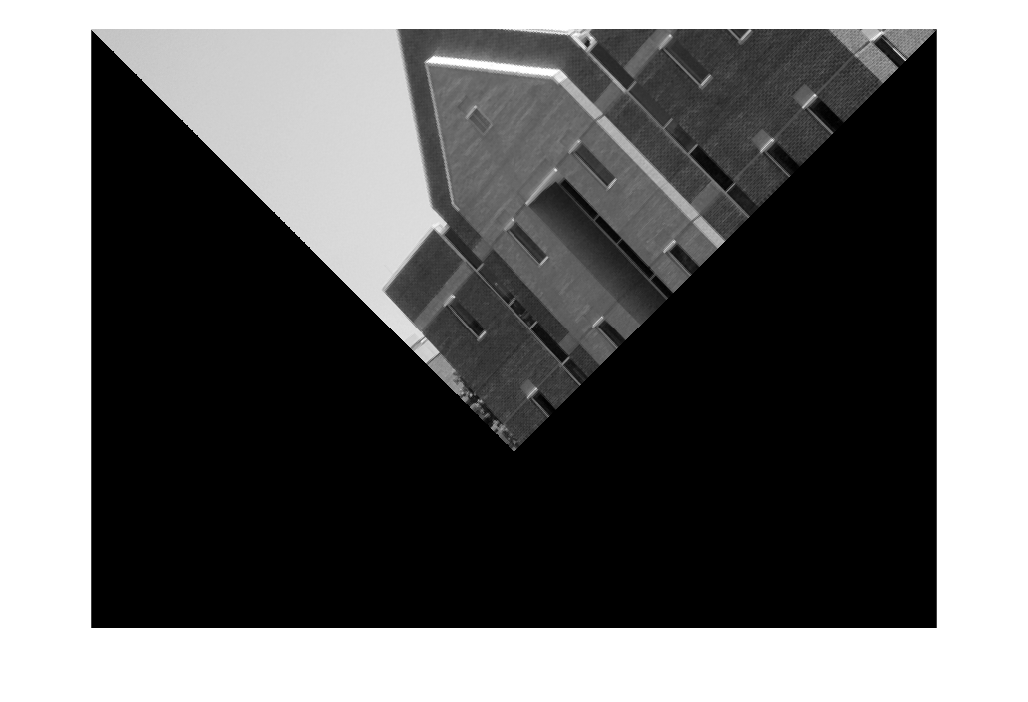

imshow(I_trasformed, [])